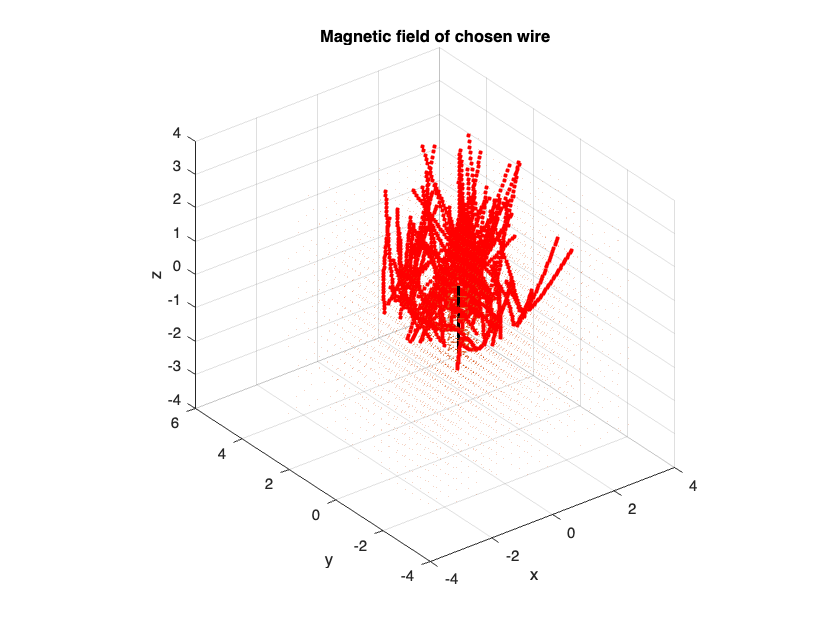

close force all;

wireA   = @(s)[cos(s),  sin(s), 0];
dwireA  = @(s)[-sin(s), cos(s), 0];
sA_min  = -pi;   sA_max = pi;

wireB   = @(s)[s,  sin(s), 0];
dwireB  = @(s)[1, cos(s), 0];
sB_min  = -pi;   sB_max = pi;

wireC   = @(s)[0, 0, s];
dwireC  = @(s)[0,   0, 1];
sC_min  = -1;    sC_max =  1;

wireID = "line";      


switch wireID
    case "loop"          
        wire  = wireA;
        dwire = dwireA;
        sMin  = sA_min;
        sMax  = sA_max;

    case "sineLoop"     
        wire  = wireB;
        dwire = dwireB;
        sMin  = sB_min;
        sMax  = sB_max;

    case "line"         
        wire  = wireC;
        dwire = dwireC;
        sMin  = sC_min;
        sMax  = sC_max;

    otherwise
        error("wireID no reconocido: %s")
end

I = 2;     

ds     = 0.05;         

x = linspace(-pi,pi,20);   
y = x;   
z = x;

[X,Y,Z] = meshgrid(x,y,z);

Bx = zeros(size(X)); 
By = Bx;  
Bz = Bx;

for i = 1:numel(X)
    P = [X(i), Y(i), Z(i)];
    B = biot_savart(P, wire,dwire,sMin,sMax,I,ds);
    Bx(i)=B(1); By(i)=B(2); Bz(i)=B(3);
end

% wire geometry for plotting (only for the chosen wire)
sPlot = linspace(sMin, sMax, 100);
rPlot = arrayfun(@(s) wire(s), sPlot, 'uni',0);
rPlot = cat(1,rPlot{:});

figure
plot3(rPlot(:,1), rPlot(:,2), rPlot(:,3), 'k', 'LineWidth',2)
hold on, grid on, daspect([1 1 1])
quiver3(X,Y,Z,Bx,By,Bz)
title('Magnetic field of chosen wire');
xlabel('x'); ylabel('y'); zlabel('z');

numParticles = 100;
pasos        = 30;
dt           = 1e-6;
q            = 1.602e-19;
m            = 9.109e-31;

%random positions
boxSize = 1.5;
xy = -boxSize + 2*boxSize .* rand(numParticles, 2); 
z  = -0.5 + 1.0 * rand(numParticles, 1);              
r0 = [xy, z];                                              

%random velocities
v0 = 1e5 * rand(numParticles,3);

posx = zeros(numParticles,pasos);
posy = posx;  
posz = posx;

for p = 1:numParticles
    r = r0(p,:);   
    v = v0(p,:);    %random velocites
    %v = [0,1e4,0];
    for k = 1:pasos
        [r,v] = rungakuta(r,v,dt,q,m, wire,dwire,sMin,sMax,I,ds);
        posx(p,k)=r(1);  posy(p,k)=r(2);  posz(p,k)=r(3);
    end
end

for k = 1:pasos
    for p = 1:numParticles
        scatter3(posx(p,1:k), posy(p,1:k), posz(p,1:k), 8, 'r', 'filled');
    end
    drawnow
end